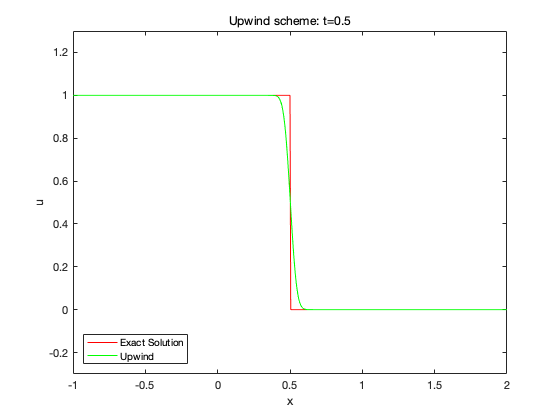

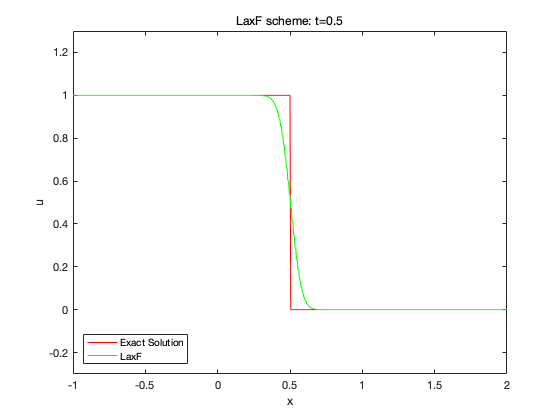

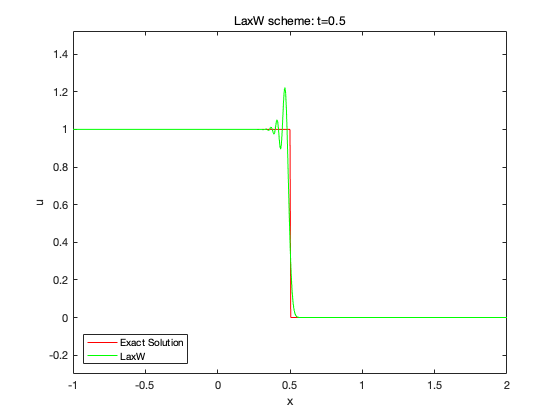

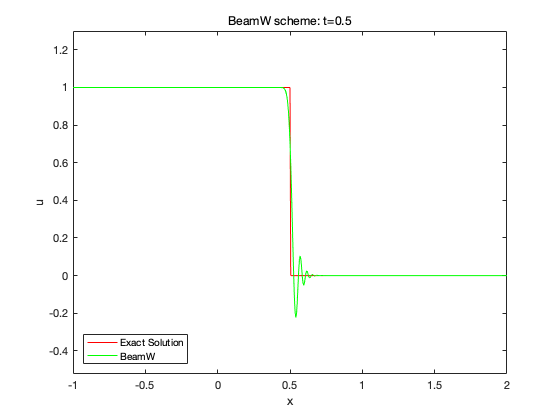

Nt=200;
t0 = 0;   tf = 0.5;   dt = (tf - t0)/Nt;
x1=-1;  x2=2;   r=0.5;   dx=dt/r;

xx = x1:dx:x2;
u0 = ExSolu(xx, 0);

uex = ExSolu(xx, tf);
scheme = ["Upwind", "LaxF", "LaxW", "BeamW"];
for i = 1:4
    figure(i);
    u = eval(scheme(i)+"(u0, xx, dx, dt, Nt)");
    plot(xx, uex, 'r-', xx, u, 'g-');
    ymin = min(u) - 0.3;    ymax = max(u) + 0.3;
    axis([x1, x2, ymin, ymax]);
    xlabel('x');ylabel('u');
    legend('Exact Solution', scheme(i), 'Location', 'SouthWest');
    title(scheme(i)+" scheme: t=0.5");
end